$\Delta T_{lm}$ forklare på side 653

## Opgaver

Ogave 11.24

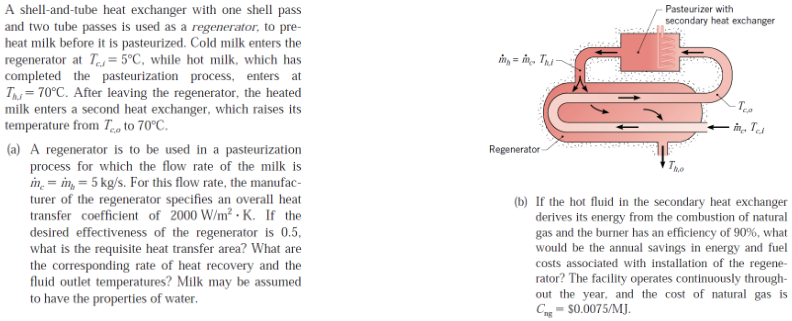

clear all
clf
format short g
CoolProp = py.importlib.import_module('CoolProp.CoolProp');
P_atm = 101325; % Pascal eller 1e5
fluid = 'water'

fluid = 'water'

K = 273.15;

C_ng = 0.0075; % $/Mj
eta_comb = 0.9;
T_ci = 5 + K; %kold mælke start temperatur
T_hi = 70 + K; %varm mælk start temperatur
T_mi = (T_ci + T_hi)/2

T_mi =        310.65


% T_co = 70 + K; %kold mælk efter anden varme veksler
q_mh = 5; %kg/s %mass flow af varm mælk
q_mc = 5; %kg/s %mass flow af kold mælk
U = 2000; %W/m^2 % overall heat coeffecient
eta = 0.5; % ønskede effektivitet

c_p = 3860; %CoolProp.PropsSI('Cpmass', 'P', P_atm, 'T', T_mi, fluid) %specificHeat_p
c_ph = CoolProp.PropsSI('Cpmass', 'P', P_atm, 'T', T_mi, fluid) %specificHeat_p

c_ph =        4179.3


c_pc = CoolProp.PropsSI('Cpmass', 'P', P_atm, 'T', T_mi, fluid) %specificHeat_p

c_pc =        4179.3


**a)**

heat capacity rate

 (side 655)

 (side 655)

NTU (number of transfer units)

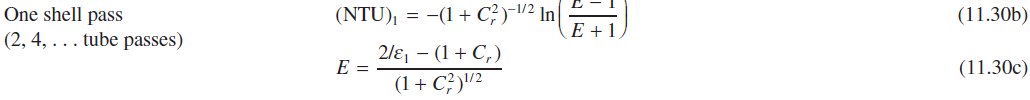

C_h = q_mh * c_ph 

C_h =         20896


C_c = q_mc * c_pc 

C_c =         20896


C_min = min([C_h, C_c])

C_min =         20896


C_max = max([C_h, C_c])

C_max =         20896



C_f = 1;
n = 2;
syms A eta_1
% eta_eq = eta == ( ( (1-eta_1 * C_min) / (1-eta_1) )^n - 1 ) *...
%                 ( ( (1-eta_1 * C_min) / (1-eta_1) )^n - C_min )^(-1);
% eta_1 = double(solve(eta_eq, eta_1))

eta_1 = eta     % why?

eta_1 =           0.5



% E = (2/eta_1 - (1 + C_min)) / (1 + C_min^2)^(1/2)

E = (2/eta_1 - (1 + C_f)) / (1 + C_f^2)^(1/2)   % why C_f???

E =        1.4142



% NTU = -(1 + C_min^2)^(-1/2) * log((E-1)/E+1)
A_eq = U * A / C_min == -(1 + C_f^2)^(-1/2) * log((E-1)/(E+1));
A = double(solve(A_eq,A))

A =        13.023


Heat recovery rate

generel expersion

with effeciency

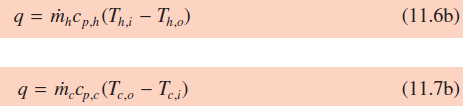

syms T_ho T_co
q_recov = eta * C_min * (T_hi - T_ci) % recoverable heat

q_recov =    6.7913e+05


q_h = C_h * (T_hi - T_ho);
T_ho_sol = double(solve(q_recov == q_h,T_ho))

T_ho_sol =        310.65


T_ho_C = T_ho_sol - K

T_ho_C =          37.5



q_c = C_c * (T_co - T_ci);
T_co_sol = double(solve(q_recov == q_c,T_co))

T_co_sol =        310.65


T_co_C = T_co_sol - K

T_co_C =          37.5


**b)**

% format longg
C_min = q_mh * c_p

C_min =        19300


q_recov = eta * C_min * (T_hi - T_ci) % recoverable heat

q_recov =       627250


year = 365 * 24 * 60 * 60

year =     31536000


E_year = q_recov * year  / 1e6 % Mj / year

E_year =     19780956


cost_savings = C_ng * E_year / eta_comb % $/yr

cost_savings =    1.6484e+05


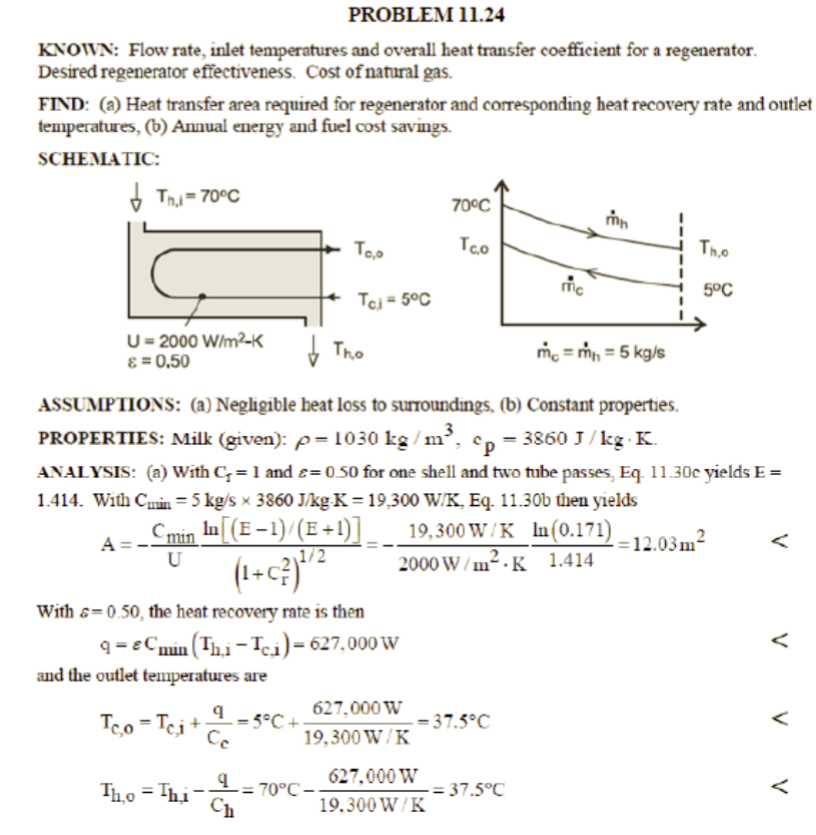

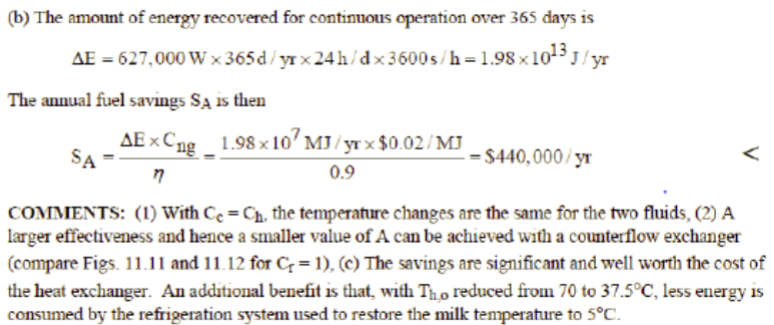

$C_{ng} = 0,02\ MJ^{-1}$ ???

Opgave 11.39

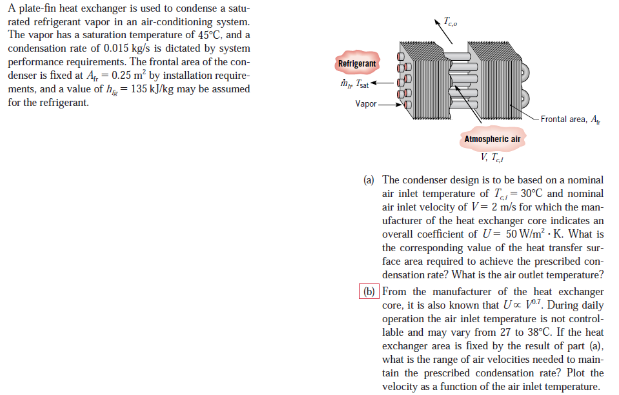

clear all
clf
format short g
CoolProp = py.importlib.import_module('CoolProp.CoolProp');
P_atm = 101325; % Pascal eller 1e5
fluid = 'air'

fluid = 'air'

K = 273.15;

T_sat = 45 + K; % mætnings temperatur af vaport refrigiant
T_ci = 30 + K; % inlet temperatur
V = 2; %m/s % luft hastighed ind
q_mtr = 0.015; %kg / s % Condensering rate af vaport refrigiant
A_fr = 0.25; %m^2 % front areal af aircondition
h_lg = 135e3; % J / kg % entalpy of vapour
U = 50; % W/(m^2 * K) % overall heat coeffecient
c_pc = CoolProp.PropsSI('Cpmass', 'P', P_atm, 'T', T_ci, fluid); %specificHeat_p
rho = CoolProp.PropsSI('D', 'P', P_atm, 'T', T_ci, fluid); %Densitet
% cs(i) = c;
% k = CoolProp.PropsSI('conductivity', 'P', P_atm, 'T', T_ci, fluid);
% mu = CoolProp.PropsSI('viscosity', 'P', P_atm, 'T', T_ci, fluid); %Dynamisk viscositet

% Pr = CoolProp.PropsSI('Prandtl', 'P', P_atm, 'T', T_ci, fluid);
% nu = mu / rho;

syms T_co
T_s = T_sat;
T_i = T_ci

T_i =        303.15


T_hi = T_sat;

 (side 655)

q_vap = q_mtr * h_lg

q_vap =         2025


% h = T*c_p
% c_ph = h_lg/T_ci % duer ikke ved tilstands ændring
% C_h = q_mtr * c_ph


q_mc = rho * V * A_fr %kg / s

q_mc =       0.58237



C_c = q_mc * c_pc

C_c =        586.15



% C_max = max([C_c, C_h])
C_min = C_c%min([C_c, C_h])

C_min =        586.15


q_max = C_min * (T_hi - T_ci)

q_max =        8792.2


eta = q_vap / q_max

eta =       0.23032


NTU = -log(1-eta)

NTU =       0.26178


A = NTU * C_min / U % m^2 % the varmeoverførende areal

A =        3.0688


Temperaturen ud kommer fra det energi tab der er i fluidet hvor der benyttes den lavest heat capacity rate $C_{min}$

q_eq =  q_vap == C_min * (T_co - T_ci);
T_co = double(solve(q_eq, T_co))

T_co =         306.6


T_co_C = T_co - K

T_co_C =        33.455


logoritmisk middel temperatur

% q = U*A*DT_lm
% DT_lm = ( (T_s -T_i) - (T_s -T_o) ) / log( (T_s - T_i) / (T_s - T_o))

**b)**

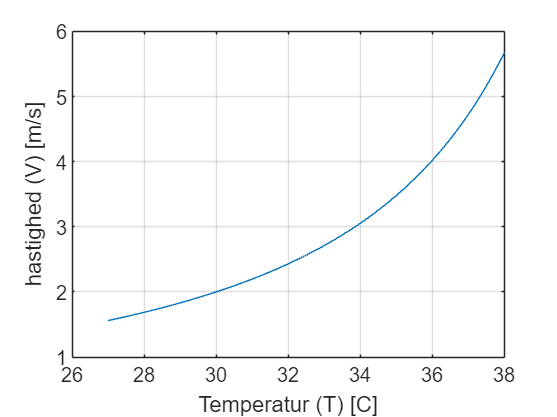

T_cis = linspace(27,38,100) + K;
% 305 - K
syms V
q_min = q_vap;

for i = 1:length(T_cis)
    T_ci = T_cis(i);
    c_pc = CoolProp.PropsSI('Cpmass', 'P', P_atm, 'T', T_ci, fluid); %specificHeat_p
    rho = CoolProp.PropsSI('D', 'P', P_atm, 'T', T_ci, fluid); %Densitet

    q_mc = rho * V * A_fr; %kg / s
    C_c = q_mc * c_pc;
    C_min = C_c; %min([C_c, C_h])
    q_max = C_min * (T_hi - T_ci);
    eta = q_min / q_max;
    
    NTU = -log(1-eta);

    U = 50 * (V/2)^0.7; % W/(m^2 * K) % overall heat coeffecient
    %hvorfor divider V med 2 her?

    A_eq = A == NTU * C_min / U; % m^2 % the varmeoverførende areal
    V_sol = double(vpasolve(A_eq,V));
    Vs(i) = V_sol; 
    etas(i) = subs(eta,V,V_sol);
end
% Vs
plot(T_cis-K, Vs)
ylabel('hastighed (V) [m/s]')
xlabel('Temperatur (T) [C]')
grid("on")

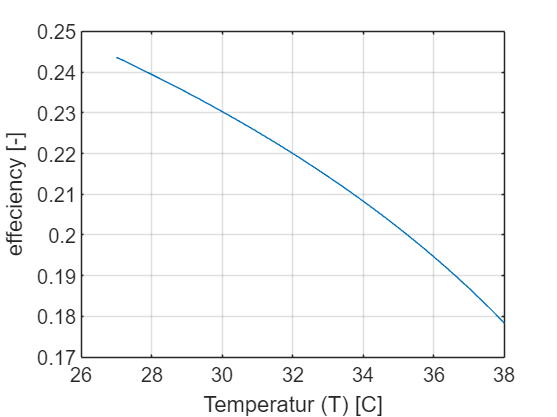


plot(T_cis-K, etas)
ylabel('effeciency [-]')
xlabel('Temperatur (T) [C]')
grid("on")